# Simulação 12 (Final 6)

## **Trajetória de referência**

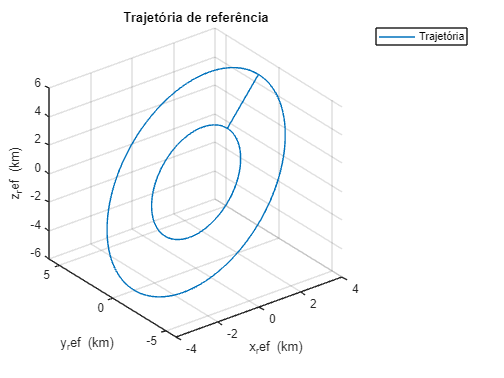

datax = Out(1).Simulation.x_ref;
datay = Out(1).Simulation.y_ref;
dataz = Out(1).Simulation.z_ref;
plot3(datax/10^3,datay/10^3,dataz/10^3);
title('Trajetória de referência');
xlabel('x_ref (km)');
ylabel('y_ref (km)');
zlabel('z_ref (km)');
legend('Trajetória');
grid;

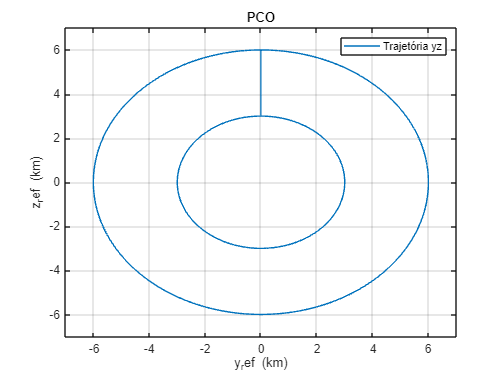

figure
datax = Out(1).Simulation.y_ref/10^3;
datay = Out(1).Simulation.z_ref/10^3;
plot(datax,datay);
title('PCO');
xlabel('y_ref (km)');
ylabel('z_ref (km)');
legend('Trajetória yz');
xlim([-7 7]);
ylim([-7 7]);
grid;

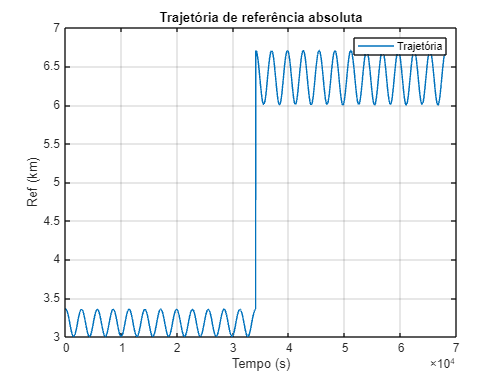

datax = Out(1).Simulation.tout;
datay = sqrt(Out(1).Simulation.x_ref.^2 + Out(1).Simulation.y_ref.^2 + Out(1).Simulation.z_ref.^2);
plot(datax,datay/10^3);
title('Trajetória de referência absoluta');
xlabel('Tempo (s)');
ylabel('Ref (km)');
legend('Trajetória');
grid;

## **Trajetória real**

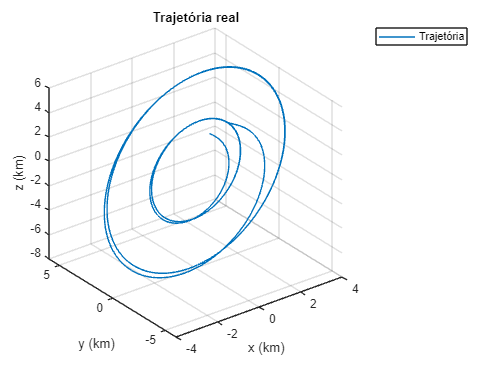

figure
datax = Out(1).Simulation.x;
datay = Out(1).Simulation.y;
dataz = Out(1).Simulation.z;
plot3(datax/10^3,datay/10^3,dataz/10^3);
title('Trajetória real');
xlabel('x (km)');
ylabel('y (km)');
zlabel('z (km)');
legend('Trajetória');
grid;

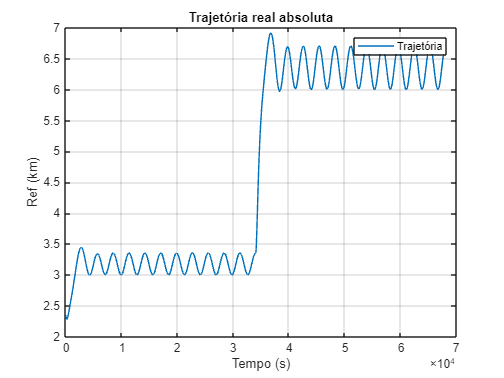

figure
datax = Out(1).Simulation.y/10^3;
datay = Out(1).Simulation.z/10^3;
plot(datax,datay);
title('PCO');
xlabel('y (km)');
ylabel('z (km)');
legend('Trajetória yz');
% xlim([-7 7]);
% ylim([-7 7]);
grid;
figure
datax = Out(1).Simulation.tout;
datay = sqrt(Out(1).Simulation.x.^2 + Out(1).Simulation.y.^2 + Out(1).Simulation.z.^2);
plot(datax,datay/10^3);
title('Trajetória real absoluta');
xlabel('Tempo (s)');
ylabel('Ref (km)');
legend('Trajetória');
grid;

## **Forças demandadas**

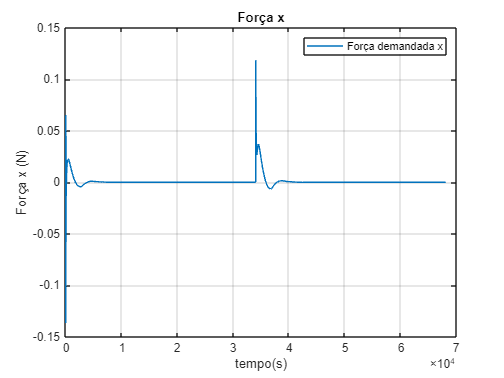

figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout;
datax = Out(1).Simulation.Fx_b_dem;
plot(tempo,datax);
title('Força x');
%xlabel('Órbitas');
xlabel('tempo(s)');
ylabel('Força x (N)');
legend('Força demandada x');
grid;

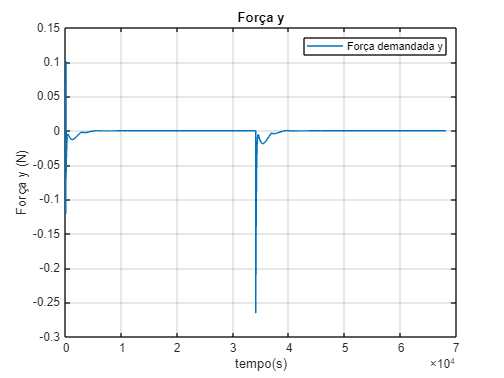


figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout;
datax = Out(1).Simulation.Fy_b_dem;
plot(tempo,datax);
title('Força y');
%xlabel('Órbitas');
xlabel('tempo(s)');
ylabel('Força y (N)');
legend('Força demandada y');
grid;

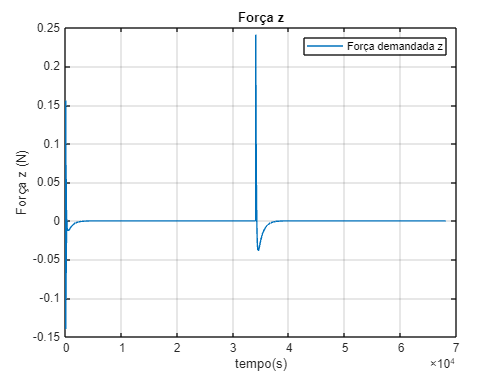


figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout;
datax = Out(1).Simulation.Fz_b_dem;
plot(tempo,datax);
title('Força z');
%xlabel('Órbitas');
xlabel('tempo(s)');
ylabel('Força z (N)');
legend('Força demandada z');
grid;

## **Forças entregues**

figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout;
datax = Out(1).Simulation.Fx_b_pro;
plot(tempo,datax);
title('Força x');
%xlabel('Órbitas');
xlabel('tempo(s)');
ylabel('Força x (N)');
legend('Força demandada x');
grid;


figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout;
datax = Out(1).Simulation.Fy_b_pro;
plot(tempo,datax);
title('Força y');
%xlabel('Órbitas');
xlabel('tempo(s)');
ylabel('Força y (N)');
legend('Força demandada y');
grid;


figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout;
datax = Out(1).Simulation.Fz_b_pro;
plot(tempo,datax);
title('Força z');
%xlabel('Órbitas');
xlabel('tempo(s)');
ylabel('Força z (N)');
legend('Força demandada z');
grid;

## **Torques demandados**

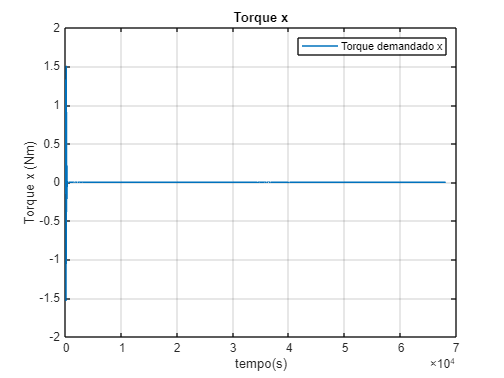

figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout;
datax = Out.Simulation.Mts_x;
plot(tempo,datax);
title('Torque x');
%xlabel('Órbitas');
xlabel('tempo(s)');
ylabel('Torque x (Nm)');
legend('Torque demandado x');
grid;

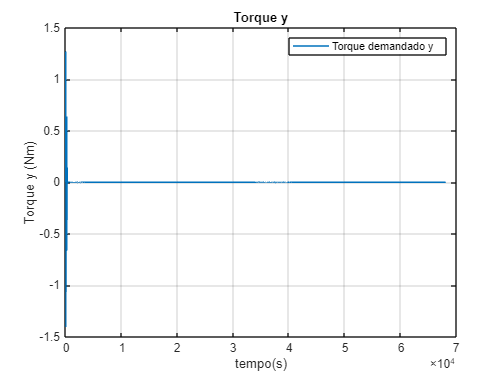


figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout;
datax = Out.Simulation.Mts_y;
plot(tempo,datax);
title('Torque y');
%xlabel('Órbitas');
xlabel('tempo(s)');
ylabel('Torque y (Nm)');
legend('Torque demandado y');
grid;

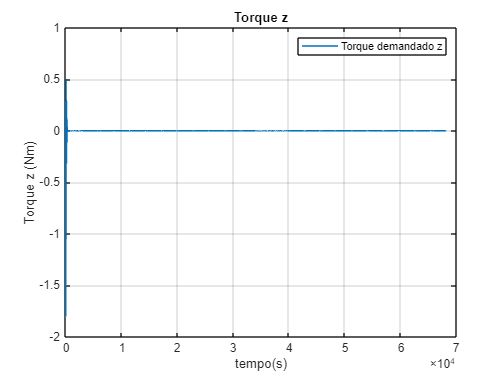


figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout;
datax = Out.Simulation.Mts_z;
plot(tempo,datax);
title('Torque z');
%xlabel('Órbitas');
xlabel('tempo(s)');
ylabel('Torque z (Nm)');
legend('Torque demandado z');
grid;

## **Erros Orbital**

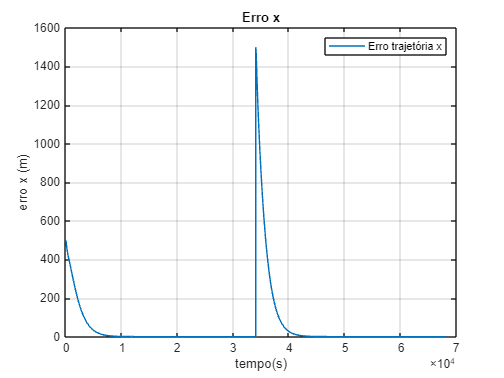

figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout;
datax = Out(1).Simulation.erro_x;
plot(tempo,datax);
title('Erro x');
%xlabel('Órbitas');
xlabel('tempo(s)');
ylabel('erro x (m)');
legend('Erro trajetória x');
grid;

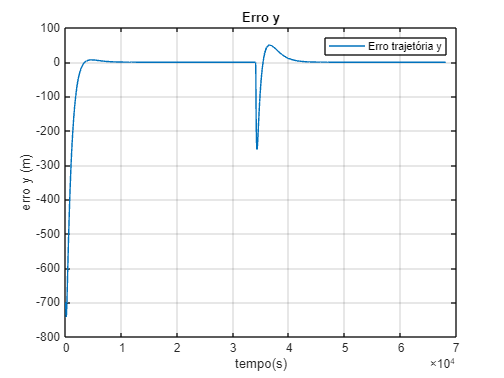

figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout;
datax = Out(1).Simulation.erro_y;
plot(tempo,datax);
title('Erro y');
%xlabel('Órbitas');
xlabel('tempo(s)');
ylabel('erro y (m)');
legend('Erro trajetória y');
grid;

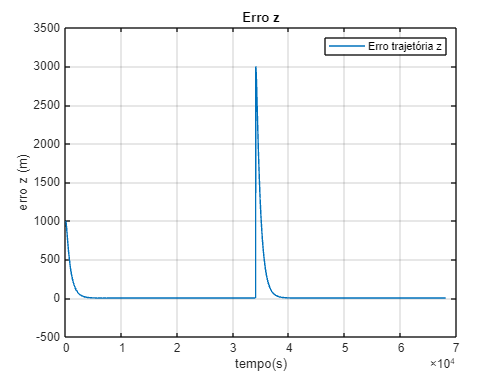

figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout;
datax = Out(1).Simulation.erro_z;
plot(tempo,datax);
title('Erro z');
%xlabel('Órbitas');
xlabel('tempo(s)');
ylabel('erro z (m)');
legend('Erro trajetória z');
grid;

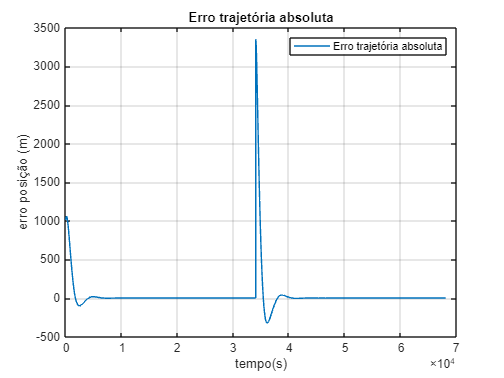

figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout;
datax = sqrt(Out(1).Simulation.x_ref.^2 + Out(1).Simulation.y_ref.^2 + Out(1).Simulation.z_ref.^2) - sqrt(Out(1).Simulation.x.^2 + Out(1).Simulation.y.^2 + Out(1).Simulation.z.^2);
%xlabel('Órbitas');
plot(tempo,datax);
title('Erro trajetória absoluta');
xlabel('tempo(s)');
ylabel('erro posição (m)');
legend('Erro trajetória absoluta');
grid;

## **Atitude**

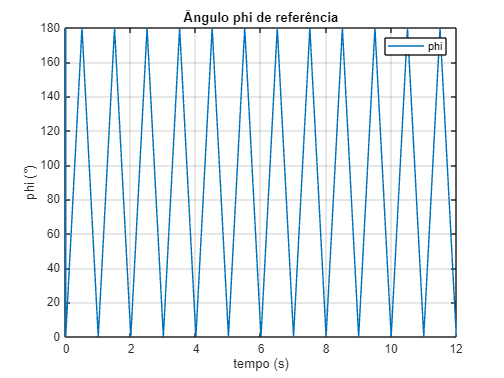

if isempty(tf)
    tf = 90832;
    orb = 16;
    step_modelo = 0.01;
end

figure
tempo = Out(1).Simulation.tout/(tf/orb);
datax = rad2deg(Out(1).Simulation.phi_ref);
plot(tempo,datax);
title('Ângulo phi de referência');
xlabel('tempo (s)');
ylabel('phi (°)');
legend('phi');
grid;

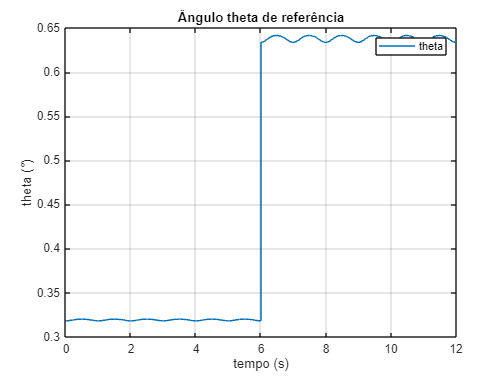

figure
tempo = Out(1).Simulation.tout/(tf/orb);
datax = rad2deg(Out(1).Simulation.theta_ref);
plot(tempo,datax);
title('Ângulo theta de referência');
xlabel('tempo (s)');
ylabel('theta (°)');
legend('theta');
grid;

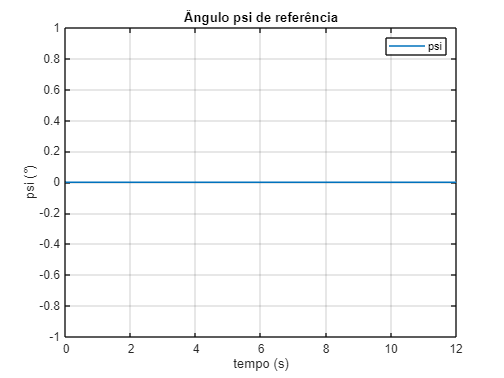

figure
tempo = Out(1).Simulation.tout/(tf/orb);
datax = rad2deg(Out(1).Simulation.psi_ref);
plot(tempo,datax);
title('Ângulo psi de referência');
xlabel('tempo (s)');
ylabel('psi (°)');
legend('psi');
grid;

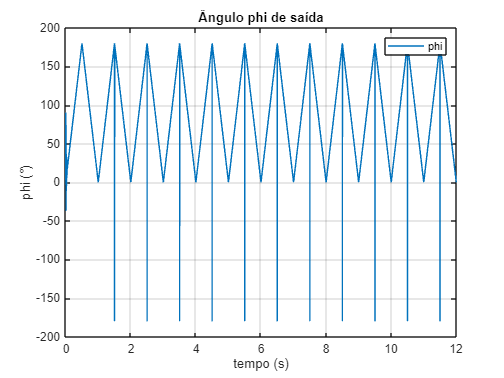

figure
tempo = Out(1).Simulation.tout/(tf/orb);
datax = rad2deg(Out(1).Simulation.phi);
plot(tempo,datax);
title('Ângulo phi de saída');
xlabel('tempo (s)');
ylabel('phi (°)');
legend('phi');
grid;

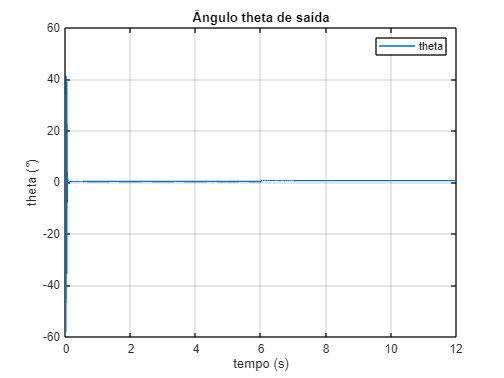

figure
tempo = Out(1).Simulation.tout/(tf/orb);
datax = rad2deg(Out(1).Simulation.theta);
plot(tempo,datax);
title('Ângulo theta de saída');
xlabel('tempo (s)');
ylabel('theta (°)');
legend('theta');
grid;

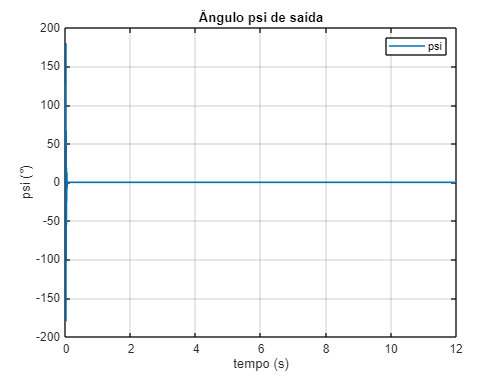

figure
tempo = Out(1).Simulation.tout/(tf/orb);
datax = rad2deg(Out(1).Simulation.psi);
plot(tempo,datax);
title('Ângulo psi de saída');
xlabel('tempo (s)');
ylabel('psi (°)');
legend('psi');
grid;

## **Erro atitude**

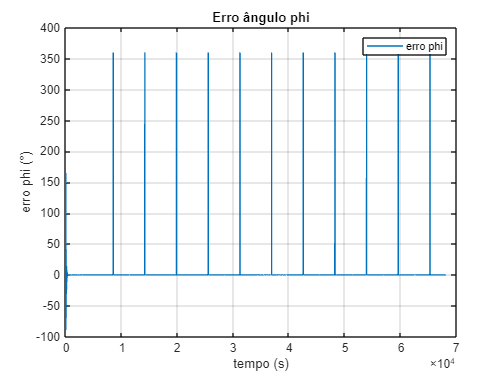

figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout;
datax = rad2deg(Out(1).Simulation.phi_ref) - rad2deg(Out(1).Simulation.phi);
plot(tempo,datax);
title('Erro ângulo phi');
%xlabel('Órbitas');
xlabel('tempo (s)');
ylabel('erro phi (°)');
legend('erro phi');
 grid;

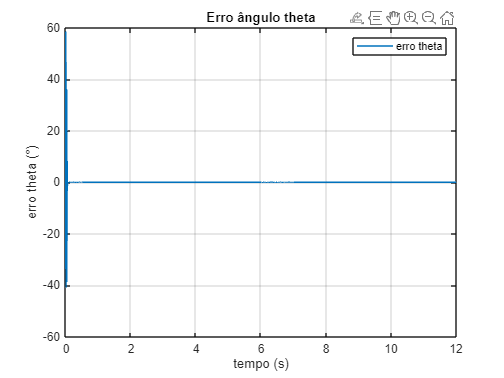

figure
tempo = Out(1).Simulation.tout/(tf/orb);
datax = rad2deg(Out(1).Simulation.theta_ref) - rad2deg(Out(1).Simulation.theta);
plot(tempo,datax);
title('Erro ângulo theta');
%xlabel('Órbitas');
xlabel('tempo (s)');
ylabel('erro theta (°)');
legend('erro theta');
grid;

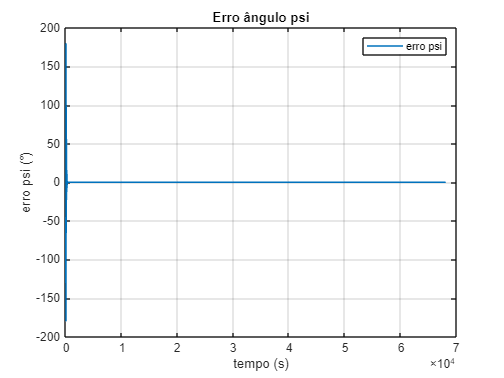

figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout;
datax = rad2deg(Out(1).Simulation.psi_ref) - rad2deg(Out(1).Simulation.psi);
plot(tempo,datax);
title('Erro ângulo psi');
%xlabel('Órbitas');
xlabel('tempo (s)');
ylabel('erro psi (°)');
legend('erro psi');
grid;

## **Tempos**

Tempo para atingir a PCO de referência inicial (min)

format long

erro_x = Out.Simulation.erro_x;
erro_y = Out.Simulation.erro_y;
erro_z = Out.Simulation.erro_z;
tempo = Out.Simulation.tout;

for i=1:1:(tf/step_modelo)/2
    if abs(erro_x(i))<=0.5 && abs(erro_y(i))<=0.5 && abs(erro_z(i))<=0.5
        t_stab = tempo(i);
        break
    end
end
t_stab = t_stab/60

t_stab =      1.779800000000000e+02


Tempo para realizar a manobra(min)

for i=((tf/step_modelo)/2+1):1:(tf/step_modelo)
    if abs(erro_x(i))<=0.5 && abs(erro_y(i))<=0.5 && abs(erro_z(i))<=0.5
        t_stab = tempo(i);
        break
    end
end
t_stab = (t_stab - tf/2)/60

t_stab =      1.853681666666667e+02


Tempo para adquirir o apontamento inicial (s)

erro_phi = rad2deg(Out.Simulation.phi_ref - Out.Simulation.phi);
erro_theta = rad2deg(Out.Simulation.theta_ref - Out.Simulation.theta);
erro_psi = rad2deg(Out.Simulation.psi_ref - Out.Simulation.psi);

for i=1:1:(tf/step_modelo)/2
    if abs(erro_phi(i))<=0.6 && abs(erro_theta(i))<=0.6 && abs(erro_psi(i))<=0.6
        t_stab = tempo(i);
        break
    end
end
t_stab

t_stab =      2.871200000000000e+02


## **Gasto de combustível**

Gasto de combustível total